# **处理缺失值和异常值**

生成缺失值、异常值

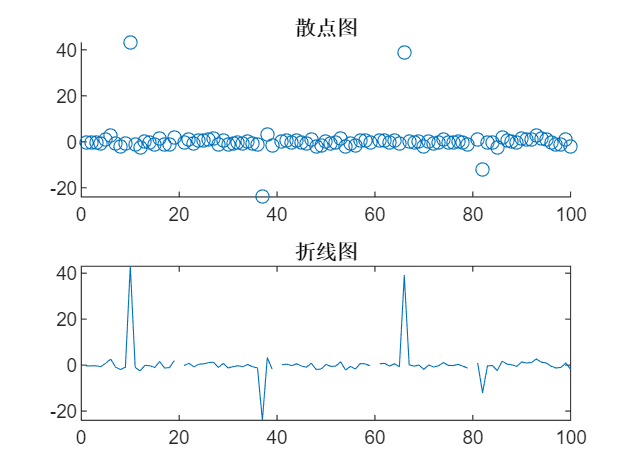

x = 1:100;
data = randn(1,100); % 均值为0，方差为1的随机数
data(20:20:80) = NaN; % 缺失值
data(10) = 43; % 异常值
data(37) = -24;
data(66) = 39;
data(82) = -12;
subplot(2,1,1);scatter(x,data);title('散点图');
subplot(2,1,2);plot(x,data);title('折线图');

实时脚本文件→任务→清理缺失数据/清理离群数据

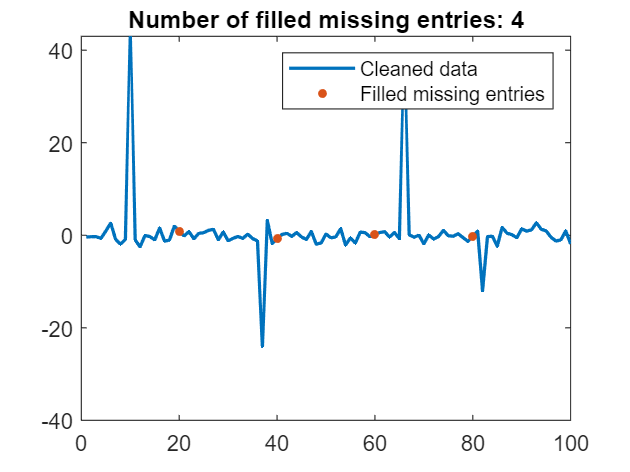

% Fill missing data
[cleanedData,missingIndices] = fillmissing(data,"linear");

% Display results
clf
plot(cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")
hold on

% Plot filled missing entries
plot(find(missingIndices),cleanedData(missingIndices),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled missing entries")
title("Number of filled missing entries: " + nnz(missingIndices))

hold off
legend

clear missingIndices

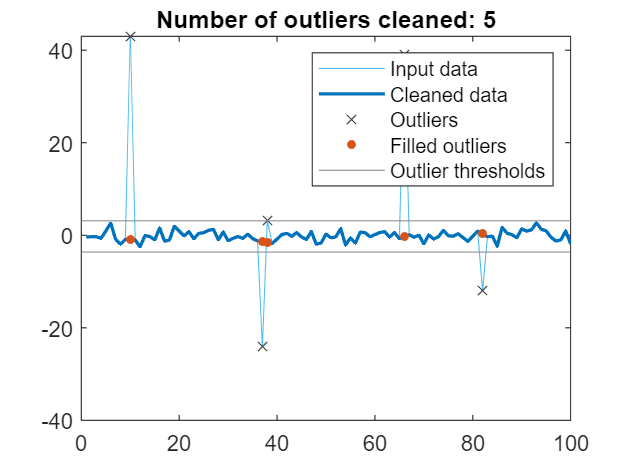

% Fill outliers
[cleanedData2,outlierIndices,thresholdLow,thresholdHigh] = ...
    filloutliers(cleanedData,"linear");

% Display results
clf
plot(cleanedData,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(cleanedData2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),cleanedData(outlierIndices),"x",...
    "Color",[64 64 64]/255,"DisplayName","Outliers")
title("Number of outliers cleaned: " + nnz(outlierIndices))

% Plot filled outliers
plot(find(outlierIndices),cleanedData2(outlierIndices),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend

clear outlierIndices thresholdLow thresholdHigh

结果

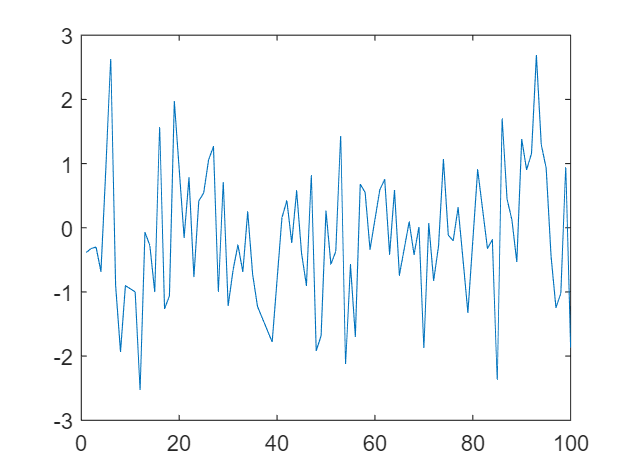

plot(x,cleanedData2);